%%1번문제
A = [1 4 2; 2 4 100; 7 9 7; 3 pi 42];
B = log(A);
a = B(2,:)

a =     0.6931    1.3863    4.6052


b = sum(B(2,:))

b = 6.6846

c = B(:, 2).*A(:,1)

c =     1.3863
    2.7726
   15.3806
    3.4342


d = max(B(:,2).*A(:,1))

d = 15.3806

e = sum(A(1,:) ./ B(1:3, 3)')

e = 3.3391


%%2번문제
%%(a)
v0 = 50;
A = 50;
g = 9.81;
t_hit = 2 * v0 * sind(A) / g;%%충돌시간
t1 = v0 * sind(A) / g;%%최고 높이일 때 시간
y_max = v0 * sind(A) * t1 - 0.5 * g * t1^2;
disp(t_hit)

    7.8088



disp(y_max)

   74.7737



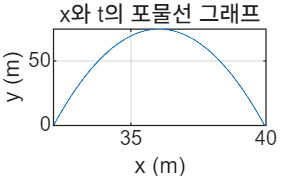

%%(b)
t = linspace(0, t_hit, 1000);
x = v0 * cosd(A) + t;
y = v0 * sind(A) * t - 0.5 * g * t.^2;

figure;
plot(x, y);
xlabel('x (m)');
ylabel('y (m)');
title('x와 t의 포물선 그래프');
grid on;

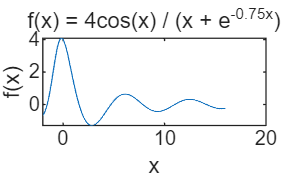


%%3번문제
clear; clc;

x = linspace(-2, 16, 1000);   % 충분히 많은 점
y = 4*cos(x) ./ (x + exp(-0.75*x));

figure;
plot(x, y);
xlabel('x');
ylabel('f(x)');
title('f(x) = 4cos(x) / (x + e^{-0.75x})')


%%4번문제
clear; clc;

price = [300; 550; 400; 250; 500];
A = [5 4 3; 3 2 4; 6 5 3; 3 5 4; 2 4 3];%%구매량
%%(a)
a = price .* A

a =         1500        1200         900
        1650        1100        2200
        2400        2000        1200
         750        1250        1000
        1000        2000        1500


%%(b)
b = sum(a, 1)

b =         7300        7550        6800


%%(c)
c = sum(a, 2)

c =         3600
        4950
        5600
        3000
        4500


%%(d)
d = sum(a(:))

d = 21650


%%5번문제
%%(a)
p1 = [5 0 -3 7 10];
p2 = [4 -7 9 2];
p = conv(p1, p2)

p =     20   -35    33    59   -36   -13   104    20



%%(b)
num = [5 -7 2 8];
den = [6 3 2];
[q, r] = deconv(num, den)

q =     0.8333   -1.5833


r =          0         0    5.0833   11.1667



%%(c)
n = [36 -8 0 2];
d = [36 -5 4 -3];
x = 5;
y = polyval(n,x)/polyval(d,x)

y = 0.9795


%%6번문제
clear n;
clc;
%% (a)
n(1).location = 'Smith St.';
n(1).max = 80;
n(1).year = 1928;
n(1).inspection = 2025;

n(2).location = 'Hope Ave.';
n(2).max = 90;
n(2).year = 1950;
n(2).inspection = 2027;

n(3).location = 'Clark St.';
n(3).max = 85;
n(3).year = 1933;
n(3).inspection = 2024;

n(4).location = 'North Rd.';
n(4).max = 100;
n(4).year = 1960;
n(4).inspection = 2023;

disp(n)

  다음 필드를 포함한 1×4 struct 배열:

    location
    max
    year
    inspection




%% (b)
n(3).inspection = 2026;

disp(n(3))

      location: 'Clark St.'
           max: 85
          year: 1933
    inspection: 2026




%% (c)
n(5).location = 'Shore Rd.';
n(5).max = 85;
n(5).year = 1997;
n(5).inspection = 2022;

disp(n)

  다음 필드를 포함한 1×5 struct 배열:

    location
    max
    year
    inspection

